# Análisis de activación de reglas de VRUs

## Regla MovinPed escenario baja densidad 

fid=fopen('TxNodes-MovinPed-S11-V0-DEN-0.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';

Total_act=[];
ind_ac=1;
Real_act=[];

ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n+1;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        Total_act(ind_ac,LD_Nodes(i,3))=delta_t*10;
        Real_act(ind_ac,LD_Nodes(i,3))=LD_Nodes(i,4);
        if LD_Nodes(i,4)>= 1 %((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
        ind_ac=ind_ac+1;        
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     27    28    28    28    28    28    28    29    30    30    30    30    30    30    30    31    31    32    32    32
    36    36    36    36    36    36    38    38    38    37    37    38    38    38    39    39    40    40    41    41
   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102
    45    44    43    43    44    43    43    43    43    43    41    42    42    42    43    42    42    43    43    43


sum(ind2)

ans =    210   210   209   209   210   209   211   212   213   212   210   212   212   212   214   214   215   217   218   218


mean(ind2,2)

ans =    29.6000
   37.9000
  102.0000
   42.8500



mean(sum(ind2))

ans = 212.3500

sum(Total_act)

ans =         5920        7580       20400        8570


sum(Real_act)

ans =         4670        5981       19265           0


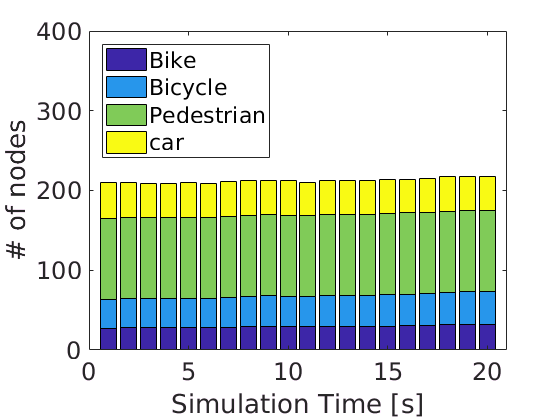





figure (1)
bar(ind2','stacked')
%title('Composición de vehiculos en Escenario S11 baja densidad');
legend('bike','bicycle','pedestrian','car','Location','NorthWest');
xlim([0 21])
ylim([0 400]);
set(gca,'FontSize',18)
ylabel('# of nodes');
xlabel('Simulation Time [s]')

## Proporción total de activación regla MovinPed.

%[ Bikenode , Bicyclenode , Pednode, Car]
sum(Real_act)./sum(Total_act)

ans =     0.7889    0.7891    0.9444         0


## Regla MovinPed escenario alta densidad 



fid=fopen('TxNodes-MovinPed-S11-V0-DEN-1.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


Total_act=[];
ind_ac=1;
Real_act=[];

ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n+1;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        Total_act(ind_ac,LD_Nodes(i,3))=delta_t*10;
        Real_act(ind_ac,LD_Nodes(i,3))=LD_Nodes(i,4);
        if LD_Nodes(i,4) > delta_t*10
            
        end
        if LD_Nodes(i,4)>= 1 %((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
        ind_ac=ind_ac+1;
        
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     37    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    45
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212
    78    78    77    76    76    76    76    75    75    75    74    74    73    73    72    72    71    70    71    71


sum(ind2)

ans =    395   394   394   394   394   394   394   392   393   393   393   393   393   393   394   393   392   393   394   395


mean(ind2,2)

ans =    40.0500
   67.3000
  212.0000
   74.1500



mean(sum(ind2))

ans = 393.5000

sum(Total_act)

ans =         8010       13460       42400       14830


sum(Real_act)

ans =         6883       12801       32068           0


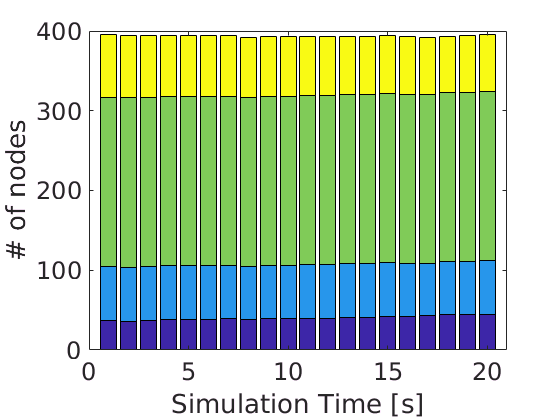





figure (1)
bar(ind2','stacked')
%title('Composición de vehiculos en Escenario S11 baja densidad');
%legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])
set(gca,'FontSize',18)
ylabel('# of nodes');

xlabel('Simulation Time [s]')

## Proporción total de activación regla MovinPed.

%[ Bikenode , Bicyclenode , Pednode, Car]
sum(Real_act)./sum(Total_act)

ans =     0.8593    0.9510    0.7563         0


## Regla OnStreet escenario baja densidad 


fid=fopen('TxNodes-OnStreet-S11-DEN-0.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


Total_act=[];
ind_ac=1;
Real_act=[];


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n+1;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        Total_act(ind_ac,LD_Nodes(i,3))=delta_t*10;
        Real_act(ind_ac,LD_Nodes(i,3))=LD_Nodes(i,4);
        if LD_Nodes(i,4)>= 1 %((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
        ind_ac=ind_ac+1;
        
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     27    28    28    28    28    28    28    29    30    30    30    30    30    30    30    31    31    32    32    32
    36    36    36    36    36    36    38    38    38    37    37    38    38    38    39    39    40    40    41    41
   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102
    45    44    43    43    44    43    43    43    43    43    41    42    42    42    43    42    42    43    43    43


sum(ind2)

ans =    210   210   209   209   210   209   211   212   213   212   210   212   212   212   214   214   215   217   218   218


mean(ind2,2)

ans =    29.6000
   37.9000
  102.0000
   42.8500



mean(sum(ind2))

ans = 212.3500

sum(Total_act)

ans =         5920        7580       20400        8570


sum(Real_act)

ans =         5920        7580         175           0


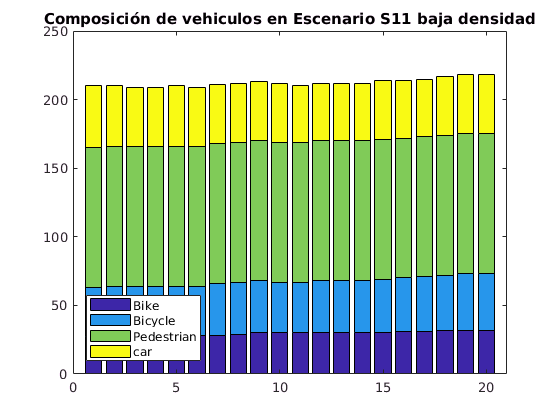




figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 baja densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])

## Proporción total de activación regla MovinPed.

%[ Bikenode , Bicyclenode , Pednode, Car]
sum(Real_act)./sum(Total_act)

ans =     1.0000    1.0000    0.0086         0


## Regla OnStreet escenario alta densidad 



fid=fopen('TxNodes-OnStreet-S11-DEN-1.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


Total_act=[];
ind_ac=1;
Real_act=[];


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n+1;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        Total_act(ind_ac,LD_Nodes(i,3))=delta_t*10;
        Real_act(ind_ac,LD_Nodes(i,3))=LD_Nodes(i,4);
        if LD_Nodes(i,4)>= 1 %((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
        ind_ac=ind_ac+1;
        
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     37    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    45
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212
    78    78    77    76    76    76    76    75    75    75    74    74    73    73    72    72    71    70    71    71


sum(ind2)

ans =    395   394   394   394   394   394   394   392   393   393   393   393   393   393   394   393   392   393   394   395



mean(ind2,2)

ans =    40.0500
   67.3000
  212.0000
   74.1500



mean(sum(ind2))

ans = 393.5000

sum(Total_act)

ans =         8010       13460       42400       14830


sum(Real_act)

ans =         8010       13460         889           0


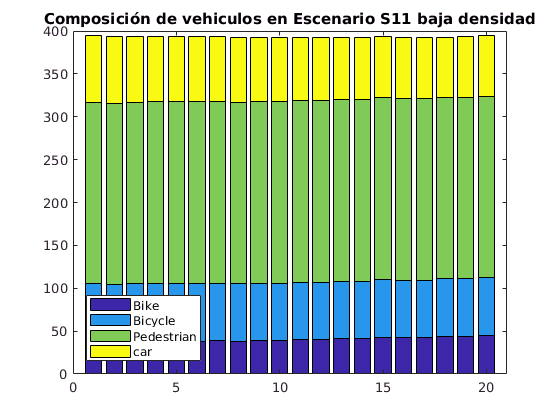





figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 baja densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])

## Proporción total de activación regla MovinPed.

%[ Bikenode , Bicyclenode , Pednode, Car]
sum(Real_act)./sum(Total_act)

ans =     1.0000    1.0000    0.0210         0
